# MOCAT-3 Workbook

## Description

MOCAT-SSEM (MIT Orbital Capacity Assessment Tool - Source Sink Evolutionary Model) is intended to be a computationally efficient way to investigate the approximate long-term evolution of the space objects (SOs) population in Low Earth Orbit (LEO). The model works by considering bulk interactions among object populations of various types in a set of coupled and nested orbital shells. The framework provides an object-oriented approach to compiling models using this approach.

The MOCAT-3 model in this workbook contains the following species: unslotted satellites (Su), derelict (D), and debris (N). 

The source and sink equations that govern this model are as follows:

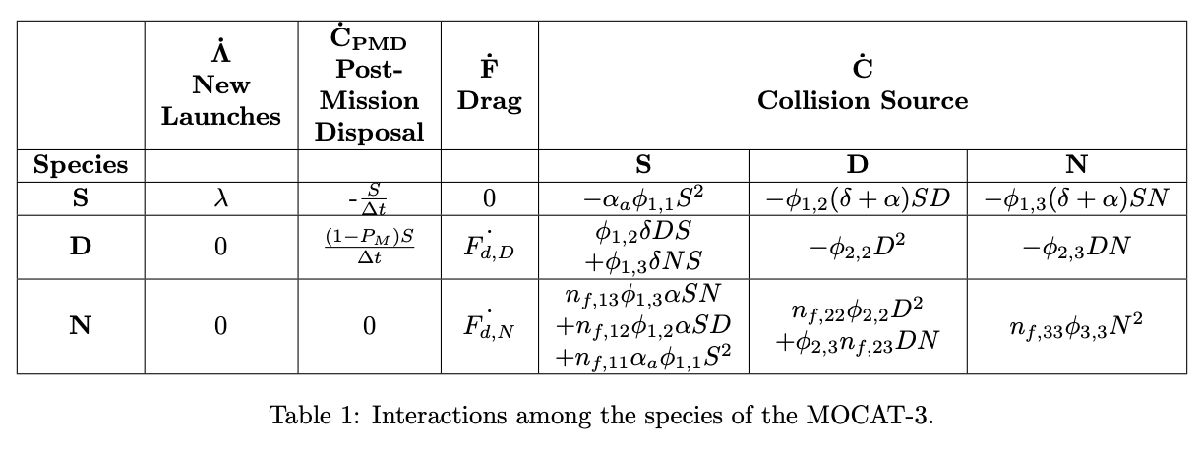

Species Names: Su- Unslotted Satellites (S in the table), D- Derelict, N- Debris.

**Note: S in MOCAT-3 correspond to Su in MOCAT-4S. **

#### Parameter Definitions:

- $\lambda$: satellite launch rate

- $\alpha$: probability of unsuccessful collision avoidance between an active satellite and an inactive object

- $\alpha_a$: probability of unsuccessful collision avoidance between two active satellites. $\alpha_a$ <  $\alpha$

- $\phi_{XY}$: intrinsic probability of collision between any species X and Y (i.e., S, D, and N), approximated from the kinetic theory of gases

- $\delta$: ratio of the density of disabling to lethal debris (this term considers the possibility that disabling collisions can generate new derelicts)

- $P_M$: probability of success of post mission disposal

- $\Delta t$: time in which satellites are active before PMD

- $\dot{F_d}$: time derivative of species quantity in a shell due to atmospheric drag

- $n_f$: number of debris fragments resulting from a collision between any species X and Y

## **How to use it:**

This MATLAB Workbook is intended to be a straightforward, clear and interactive way to build familiarity with the MOCAT-SSEM model framework. The code is explained in comments in as much detail as possible for ease of use and clarity. **This workbook is intended to be a simple introduction and does not describe all functionality of the MOCAT-SSEM framework.**

Each model is built with a top-level simulation object. The simulation object has a scen_properties object, which sets global parameters, and a set of species with their own species_properties objects that define parameters for that species. The simulation object will automatically handle equation compilation and numerical integration of the model based on the provided parameters.

The recommended workflow beings with defining the scen_properties object and species before assembling and running the model.

To begin, you set the properties of the scenario you want to run such as the altitudes to be considered and atmospheric model to use, in **Define Scenario Properties**. Simply change the values that the variables are set to. 

As explained previously, MOCAT-3 considers 3 different species types, Su, D and N. You can set the properties of these species, such as the mass of derelict objects and launch rate of satellites in **Define Species Properties**. 

The sections **Collision Modeling **and **Define Initial population** require no user input but are necessary code. The first calculates the population gain/loss between species as they collide. The second, takes in the scenario properties you set earlier and a list of satellites from the file ('initialized.mat') and creates an array (x0) of of the number of species in each shell for the model at the start of the simulation.

You can select which, if any, visualizations of results you want to see in the final section, **Make and Run Simulation**. The plot for the evolution of total species numbers in each shell is already selected in my_sim.total_species_evol_vis();. To see the other visualizations, simply uncomment them (remove the % at the start of the line). You can also export numerical results for additional analysis as you desire.

Once you've finished all the inputs you'd like, simply run this workbook (F5) and it will begin. 

## Set up paths and clear workspace to run file.

This is necessary so that the model can find the necessary classes and functions. Clearing your workspace is not strictly necessary, but using an existing workspace may result in unintended interactions.

clear
clc

% The demo workbooks are in a subfolder of the main directory. We need to
% add the path recursively for the main directory.
fileName = matlab.desktop.editor.getActiveFilename;
[folder, ~, ~] = fileparts(fileName);
folder = fullfile(folder, '..');
addpath(fileparts(folder));
addpath(genpath(folder));
cd(folder);

## Define Scenario Properties

Set simulation parameters such as start time, duration, and time steps:

scenario_properties = MOCATSSEM_Scen_Prop_Cons( ...
    start_date = datetime(2022,1,30,9,42,28), ... # Starting date (year, month, day, hour, minute, second)
    simulation_duration = 100.0, ... % Years of simulation to run
    steps = 1000, ... % Number of steps to run in simulation
    min_altitude = 200, ... % Maximum altitude shell in km
    max_altitude = 900, ... % Minimum altitude shell in km
    shells = 10, ... % Number of altitude shells
    ... % We create this many equally spaced shells between the minimum and maximum altitudes
    delta = 10, ... %ratio of the density of disabling to lethal debris
    ... % this term, delta, considers the possibility that disabling collisions can generate new derelicts
    integrator = @ode15s); % MATLAB integrator used to run simulation
    % We typically use ode15s because models with many shells are often stiff systems of differential 
    % equations that run faster with ode15s.
  

You can choose between a static exponential or JB2008-based atmospheric density models. The static exponential model is not time dependent, and will run faster than JB2008. The JB2008 model is time/space-weather dependent and more accurate, but runs slower. You can see spikes in the JB2008 graph as the density changes over time. 

Set atmospheric density model:

atm_density_choice = "JB2008";
switch atm_density_choice
    case "JB2008"
        scenario_properties.density_filepath = fullfile(".","Drag", "Atmosphere Model", "JB2008", "Precomputed", "dens_highvar_2000.mat");
        scenario_properties.dens_model = @JB2008_dens_func;
        scenario_properties.time_dep_density = true;
    case "Static Exponential"
        scenario_properties.dens_model = @static_exp_dens_func;
        scenario_properties.time_dep_density = false;
end

Processes and saves the scenario properties you just set to be used in the simulation:

scen_properties = scen_properties_class(scenario_properties);

To access and edit ODE options, e.g.: 

- scen_properties.options.AbsTol = 1e-2;

- scen_properties.options.RelTol = 1e-2;

% scen_properties.options

## Define Species Properties

Define launch function: 

- Null: Launches no new satellites ever. May be helpful in debugging.

- Constant: Launches a constant number of satellites, with that number set by species_properties.lambda_constant in the Su species properties below.

Choose your launch function to determine the rate of new active satellites (species Su are inserted into orbit)

launch_func_choice = "Null";
switch launch_func_choice
    case "Null"
        launch_func_sat = @launch_func_null;
    case "Constant"
        launch_func_sat = @launch_func_constant;
        lambda_constant = num2cell(500 * rand(scen_properties.N_shell,1));
end

 Define drag function:

my_drag_func = @drag_func;

**species_properties** is a struct object that takes in your inputs for the properties of a species. Once all the properties of a certain species have been set, they are saved and processed for the model by the species function. Then we clear species_properties at the end of each section so we can use it again for the next species (and we dont get properties left over from the last species).

species_properties = struct;

#### List of Species Properties

- *sym_name* - Symbolic name for species

- *Cd *- Coefficient of drag, unitless

- *mass* - Mass of species [kg]

- *radius *- Radius of species [m]

- *A *- Area of species in [m^2]

- *amr *- Area/mass ratio in [m^2/kg]

- *beta* - Ballistic coefficient

- *slotted *- Whether species is slotted or not, which reduces collision risk versus other slotted objects [bool]

- *drag_effected* - Whether object decreases altitude due to drag or not [bool]

**Only for unslotted satellites (Su)**

- *lambda_constant - *Determines launch rate if launch function is constant 

- *maneuverable *- Whether species is maneuverable or not [bool]

- *deltat* - Lifetime of spacecraft [years]

- *Pm* - Post-mission disposal efficacy, if post-mission disposable is successful, the satellite is removed from the simulation. If it fails, the satellite transitions to a derelict [Float [0,1]]

- *alpha -* failure rate of collision avoidance vs. inactive

- alpha_active - failure rate of collision avoidance vs. other active

- *RBflag - If the object is a rocket body (which influences collision properties)*

#### Define species properties for unslotted satellites

% Su
species_properties.sym_name = "Su";  
species_properties.Cd = 2.2; % [-]
species_properties.mass = 223; % [kg]
species_properties.radius = 1.490/2; % [m]
species_properties.A = 1.741; % [m^2]
species_properties.amr = species_properties.A./species_properties.mass;  % [m^2/kg]
species_properties.beta = species_properties.Cd*species_properties.amr; % BC

% Orbit Properties
species_properties.slotted = false; % bool

% Capabilities
species_properties.drag_effected = false;
species_properties.active = true; % bool, use alpha_active for collisions vs. trackable
species_properties.maneuverable = true; % bool, use alpha_active for collisions vs. trackable
species_properties.trackable = true; % bool, others can avoid this with alpha.
species_properties.deltat = 5.0; % lifetime of spacecraft in years
species_properties.Pm = 0.95; % Post-mission disposal efficacy Float [0,1]
species_properties.alpha = 0.2; % Efficacy of Collision Avoidance vs. inactive
species_properties.alpha_active = 0.01; % Efficacy of Collision Avoidance vs. other active 
species_properties.RBflag = 0;
if launch_func_choice == "Constant"
    species_properties.lambda_constant = lambda_constant; 
end

Create species instance with a launch function, post-mission disposable function, drag function, species properties which are specific to satellites, and scenario properties which are specific to the simulation. If post-mission disposable is successful (based on probabily Pm), the satellite is removed from the simulation. If it fails, the satellite transitions to a derelict.

Su_species = species(launch_func_sat, @pmd_func_sat, my_drag_func, species_properties, scen_properties);
species_properties = struct;

#### Define species properties for derelict

Derelict properties should generally match the properties of the satellite species as that is the species they originated from. 

% D
species_properties.sym_name = "D";
species_properties.Cd = Su_species.species_properties.Cd;
species_properties.mass = Su_species.species_properties.mass;
species_properties.radius = Su_species.species_properties.radius;
species_properties.A = Su_species.species_properties.A;
species_properties.amr = Su_species.species_properties.A/Su_species.species_properties.mass(1);  % m^2/kg
species_properties.beta = Su_species.species_properties.Cd*Su_species.species_properties.amr; % ballistic coefficient
species_properties.drag_effected = true; % bool, does object decrease altitude due to drag
species_properties.maneuverable = false; % bool, use alpha_active for collisions vs. trackable
species_properties.active = false;

Create species instance for derelict. There is no launch of derelict. @pmd_func_derelict describes how many satellites fail post-mission disposal and become derelict. If post-mission disposable is successful (based on probabily Pm), the satellite is removed from the simulation. If it fails, the satellite transitions to a derelict. The instance also includes the atmospheric drag function, species properties which are specific to derelict and scenario properties which are specific to the simulation.

D_species = species(@launch_func_null, @pmd_func_derelict, my_drag_func, species_properties, scen_properties);
D_species.species_properties.pmd_linked_species = Su_species;
species_properties = struct;

#### Define species properties for debris.

% N
species_properties.sym_name = "N";
species_properties.Cd = 2.2; % unitless
species_properties.mass = 0.640; 
species_properties.radius = 0.180/2; % m
species_properties.A = 0.020;
species_properties.amr = species_properties.A/species_properties.mass;  % m^2/kg
species_properties.beta = species_properties.Cd*species_properties.amr; % ballistic coefficient
species_properties.drag_effected = true; % bool, does object decrease altitude due to drag
species_properties.maneuverable = false; % bool, use alpha_active for collisions vs. trackable
species_properties.active = false;

Create species instance for debris. There is no launch of debris. We assume that no PMD occurs for debris and select the pmd_func_none function. The instance also includes the atmospheric drag function, species properties which are specific to the debris and scenario properties which are specific to the simulation.

N_species = species(@launch_func_null, @pmd_func_none, my_drag_func, species_properties, scen_properties);
species_properties = struct;

Add all species to scenario properties.

scen_properties.species = [Su_species, D_species, N_species];
scen_properties.species_cell = struct('Su', Su_species,'D', D_species, 'N', N_species);

## Collision Modeling

The `make_collision_pairs_MOCAT3.m `function calculates collision coefficients for the table above, based on the species properties and NASA's standard break-up model, and adds the collision terms to the source sink equations. The `make_collision_pairs_MOCAT3.m `function is specific to MOCAT-3. The generalized function for collision modelling for other MOCAT versions is `make_collision_pairs_SBM.m`

scen_properties = make_collision_pairs_MOCAT3(scen_properties, Su_species, D_species, N_species)

Creating species pairs...
Done


scen_properties =   scen_properties_class with properties:

                                  re: 6.3781e+03
                             N_shell: 10
                               h_max: 900
                               h_min: 200
                              N_step: []
                              deltaH: 70
                               alpha: []
                        alpha_active: []
                                  Dt: []
                            slot_par: []
                               delta: 10
                                   P: []
                                  Cd: []
                                mass: []
                                   A: []
                            diameter: []
                               v_imp: 10
                              v_imp2: [10 10 10 10 10 10 10 10 10 10]
                                  LC: 0.1000
                       deg_intrinsic: []

## Define Initial Population

This section creates an initial population for satellites, derelict and debris. The `MC2SSEM_population` function takes a list of space objects from `initialized.mat` and categorizes them into satellites, derelict and debris. x0 is a total count of each species in each shell that we will start the simulation from.

Species order and definition (NOTE: do not change the order): 

- S = Active slotted satellites

- D = Derelict objects

- N = Debris objects

- Su = Active unslotted satellites

- B = Rocket bodies

- U = Lethal non-trackable debris objects (AKA N with trackable = False)

scen_properties.species_types = [isfield(scen_properties.species_cell,'S') && ~isempty(scen_properties.species_cell.S),...
                                 isfield(scen_properties.species_cell,'D') && ~isempty(scen_properties.species_cell.D),...
                                 isfield(scen_properties.species_cell,'N') && ~isempty(scen_properties.species_cell.N),...
                                 isfield(scen_properties.species_cell,'Su') && ~isempty(scen_properties.species_cell.Su),...
                                 isfield(scen_properties.species_cell,'B') && ~isempty(scen_properties.species_cell.B),...
                                 isfield(scen_properties.species_cell,'U') && ~isempty(scen_properties.species_cell.U)];
load('initialized.mat', 'sats');
x0 = MC2SSEM_population(sats,scen_properties);
% Display starting population
for spec_index = 1:length(scen_properties.species)
   spec_names(spec_index) = scen_properties.species(spec_index).species_properties.sym_name;
end

T = array2table(x0, 'VariableNames', spec_names);
disp(array2table([[1:scen_properties.N_shell]',x0], 'VariableNames', ['Shell', spec_names]))

    Shell     Su      D      N  
    _____    ____    ___    ____

      1         2      9      26
      2        25     10      36
      3        72     50     139
      4       355    154     304
      5      3241    151     263
      6       430    144     436
      7       158    179     615
      8       102    203    1143
      9       162    273    1816
     10         0      0       0



## Build Model

`The simulation_class` is responsible for building and running the model. The `build_model()` function compiles the equations. It adds together all of the terms (regarding launch, collisions, post-mission disposal, and atmospheric drag).

Building the model is only required once in order to run the model. If the user doesn't want to change input parameters, you can run the model again without rebuilding the equations.


my_sim = simulation_class(scen_properties.species, scen_properties);
my_sim.build_model();

Building model...


ans =   simulation_class with properties:

       species_list: [1×3 species]
    scen_properties: [1×1 scen_properties_class]
          equations: [10×3 sym]
            results: []
           xdot_eqs: []
           xdot_fun: []
            var_col: []
    drag_term_upper: []
      drag_term_cur: []


Now processing Su
Now processing D
Now processing N
Done building model.


## Run Simulation

`run_model()` is where the simulation model is actually run. It takes a list of initial conditions (x0).

The function also accepts many optional parameters: 

- progressBar - Displays percentage of simulation run in another window - bool 

- disp_times - Displays time steps in console - bool

- start_date - Start date of simulation - MATLAB datetime object

- simulation_duration - Years of simulation to run - double

- N_step - Number of simulations steps to run - int

x0 = reshape(table2array(T), [], 1);% Turn initial population into a vector
my_sim.run_model(x0, 'progressBar', true, 'disp_times', false) 

## Plots

Produces a Figure with subplots for each species population evolution over time 

Producing visuals for the evolution of each species.


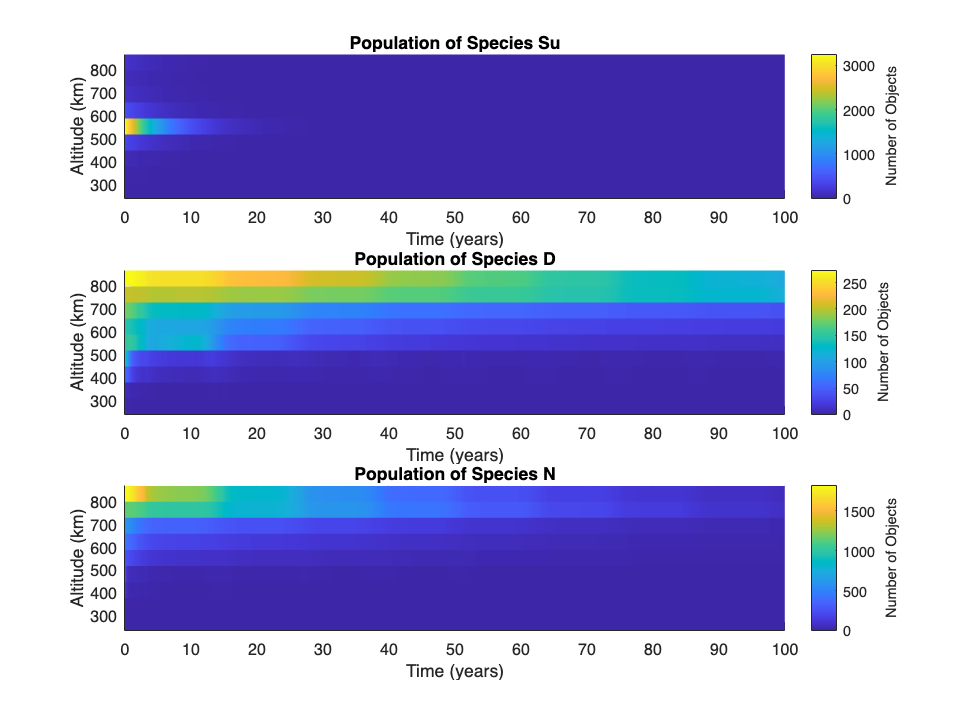

my_sim.total_species_evol_vis();

Produces a Figure with subplots for each species population density evolution over time 

Producing visuals for the evolution of each species' density.


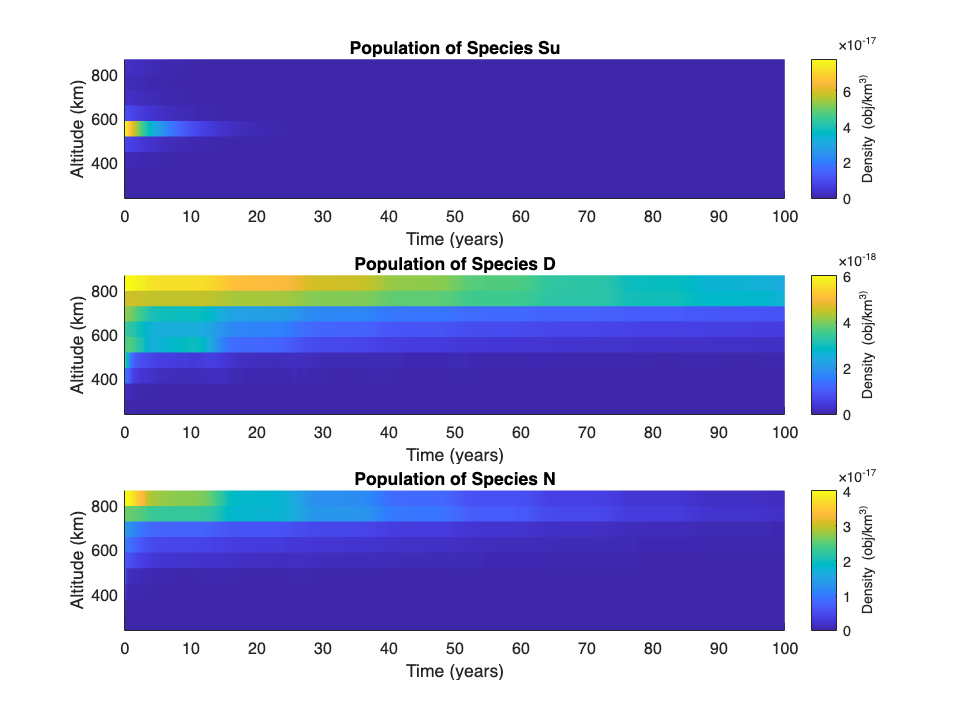

my_sim.density_species_evol_vis();

Produces a Figure for the evolution of the total population of each species over time across all shells 

Producing visual of the change in populations across all altitudes vs time.


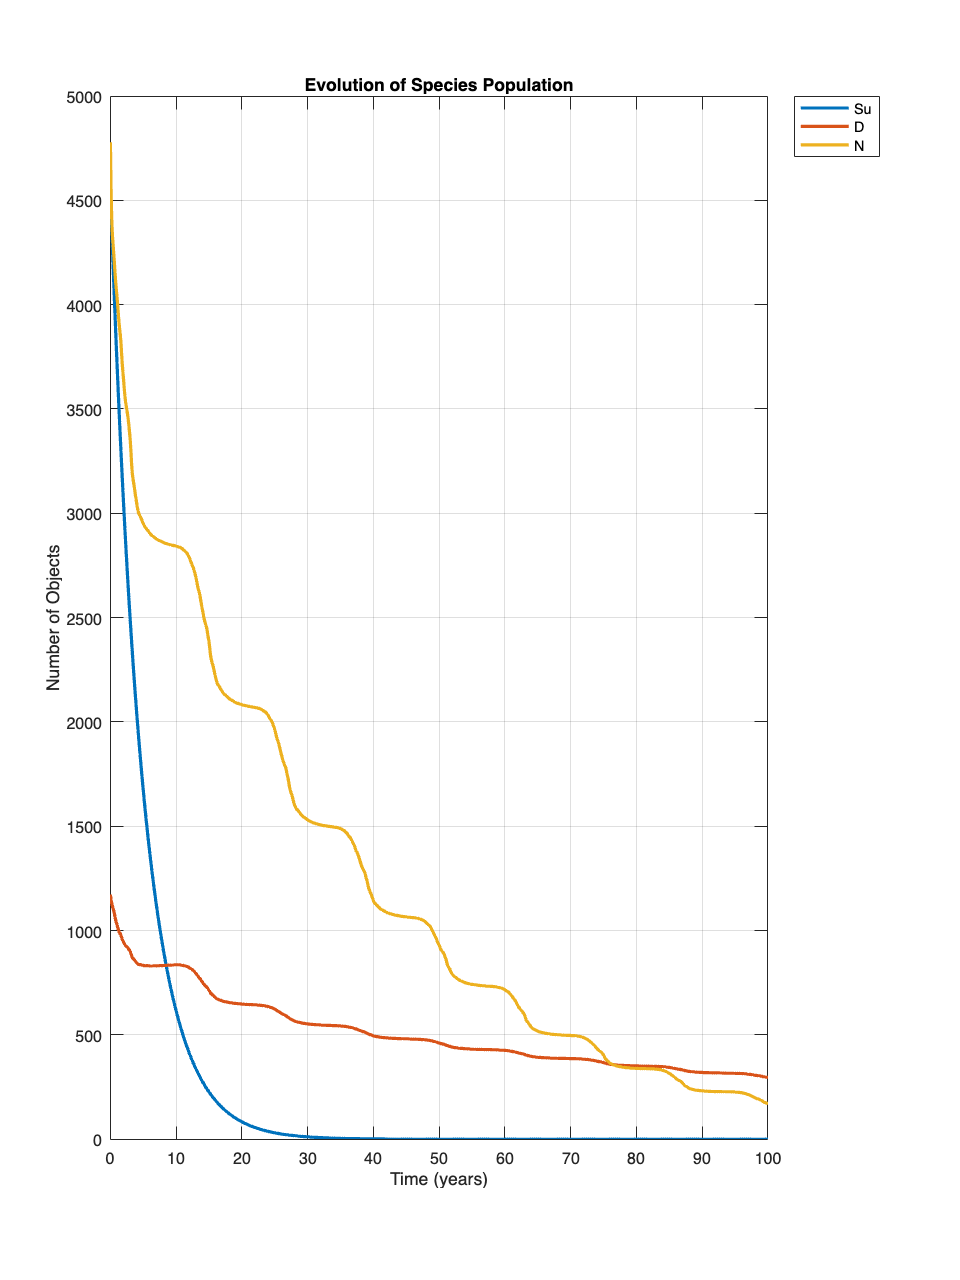

my_sim.pop_vs_time_vis();

Graphs the rate of change for the total inactive population added across all altitudes at each time. 

percentage = (bool, defaults to false) that expresses rate of change in percentage terms. 

% my_sim.total_deb_pop_time_deriv('percentage', true) 

Produces a Figure with subplots for numerical derivative of each inactive species population evolution over time constraint is the value used in the color scale.

percentage is bool (default false) for whether to use percentage or absolute.

color_scale_crop_percentiles is pair (default [0, 100]). Color scale will be  set based on the inclusive range from the lower value to the higher value.

% my_sim.total_deb_species_deriv_evolv_vis();

Produces a Figure for the evolution of the total population of all objects over time across all shells 

Producing visual of the change in the total population across all altitudes vs time.


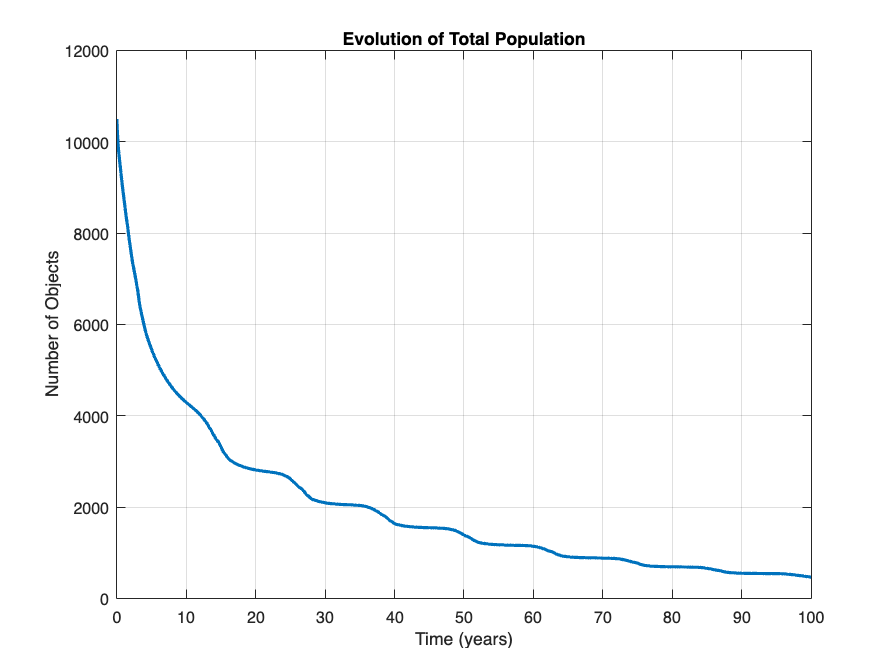

my_sim.tot_vs_time_vis();

Produces a Figure per species for the evolution of the total population of each species over time across all shells 

Producing visuals of the change in each species across all altitudes vs time.


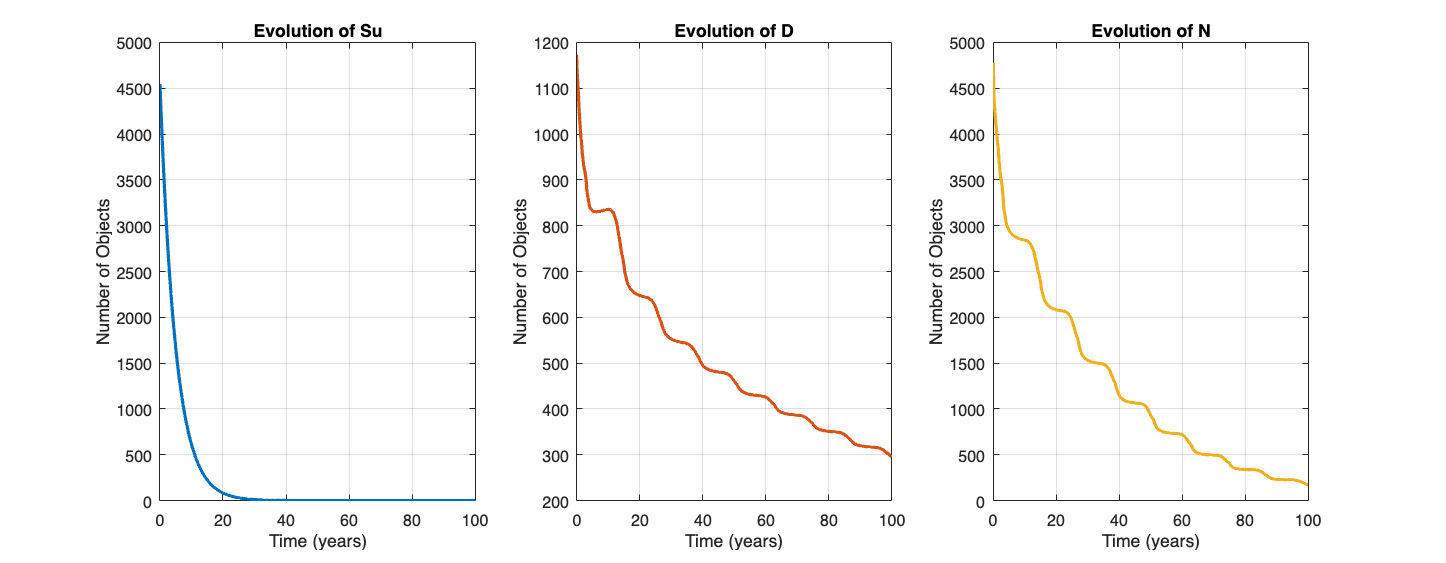

my_sim.species_time_vis();

Displays total spatial density in each shell over time 

Producing visuals for the evolution of total population density.


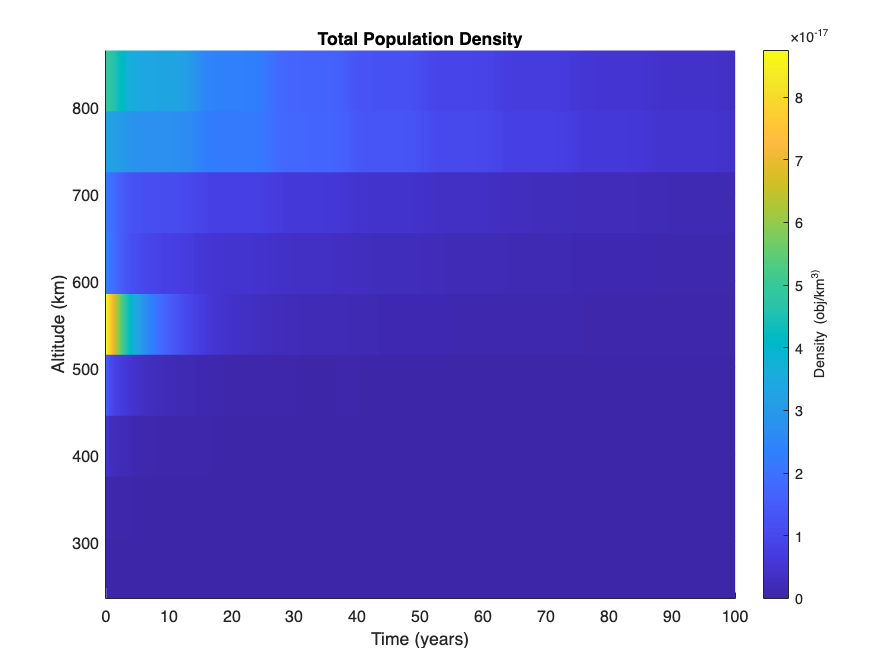

my_sim.density_vs_time();

Computes and displays Number_Time_Product

% my_sim.num_time_prod(x0);

Produces a Figure comparing the total initial number of objects and the total final number of objects 

% my_sim.init_vs_final_vis();

Produces a Figure comparing the initial population of each species alongside a plot of the final population of each species 

Producing visual for the initial and final species populations.


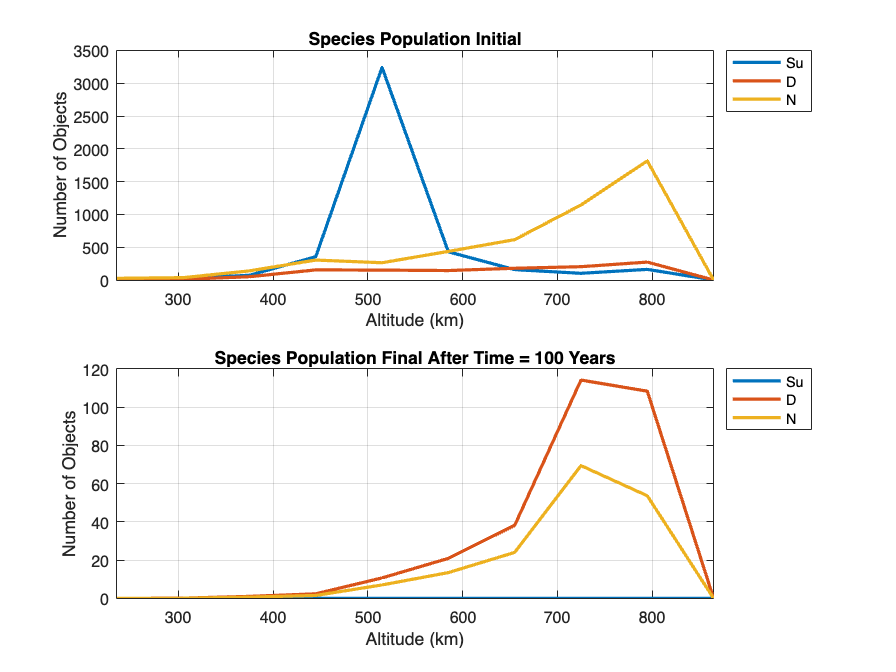

my_sim.init_and_final_vis();

Produces a Figure showing number of debris across altitudes by debris type 

% my_sim.final_debris_vis();

Computes and displays cumulative Criticality of Space Index - CSI

Producing two visuals of CSI.


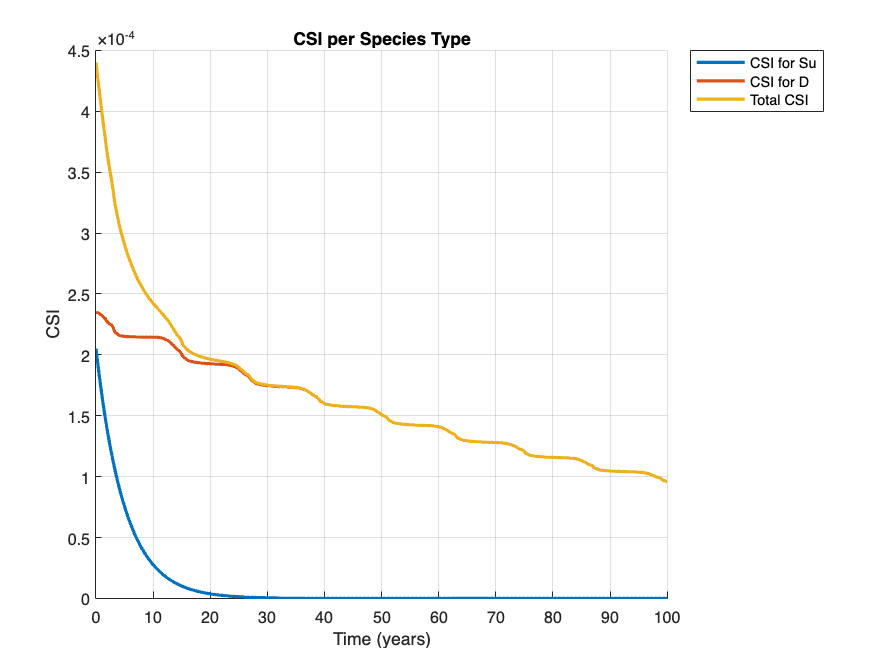

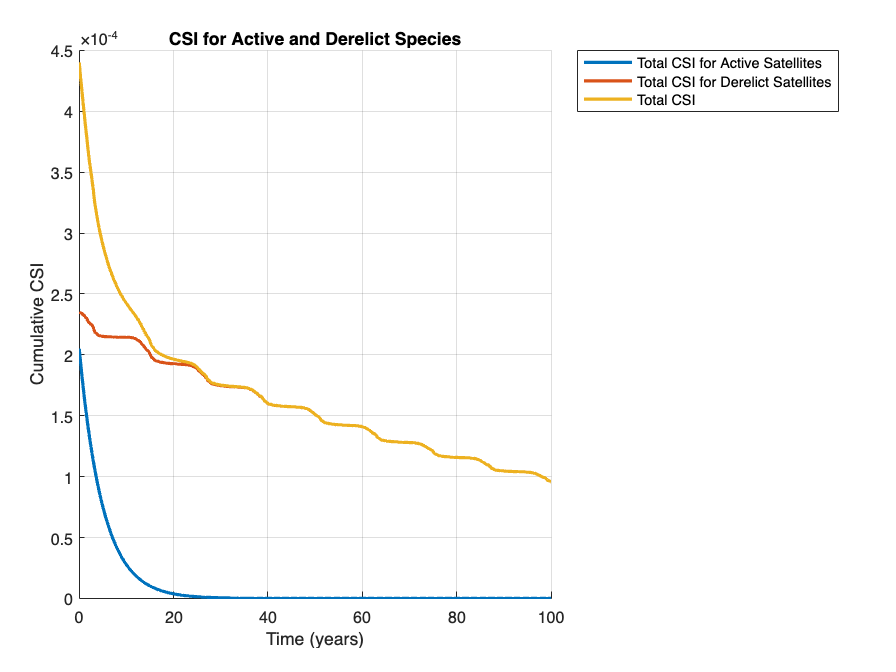

my_sim.cum_CSI()

Close all figures created (or run this line in your command line)

% close all